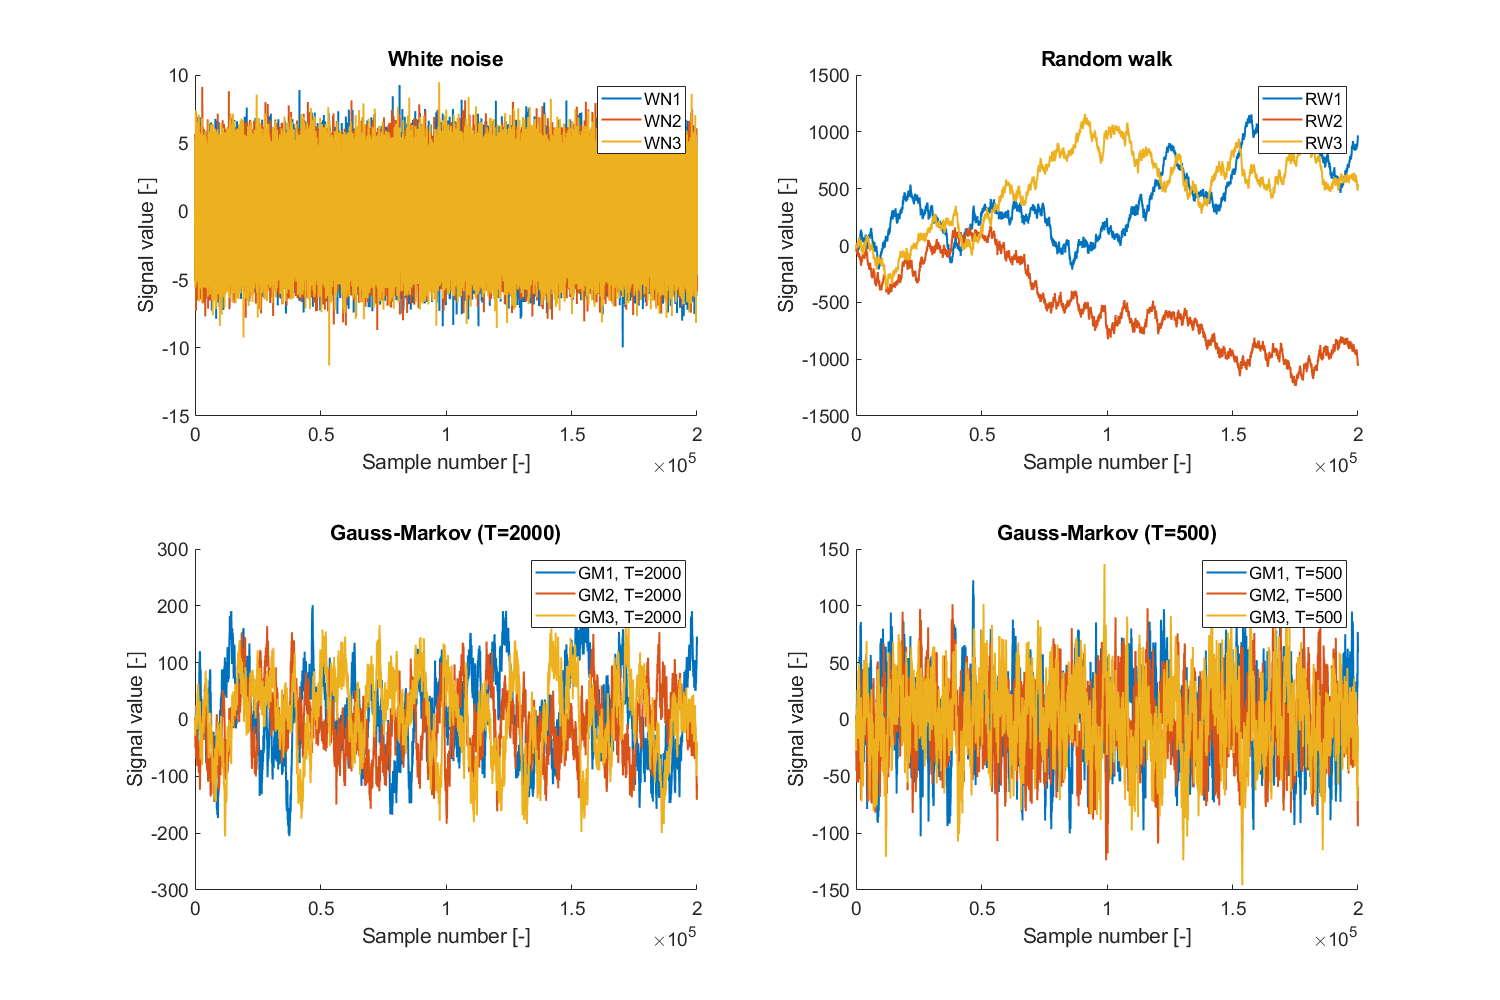

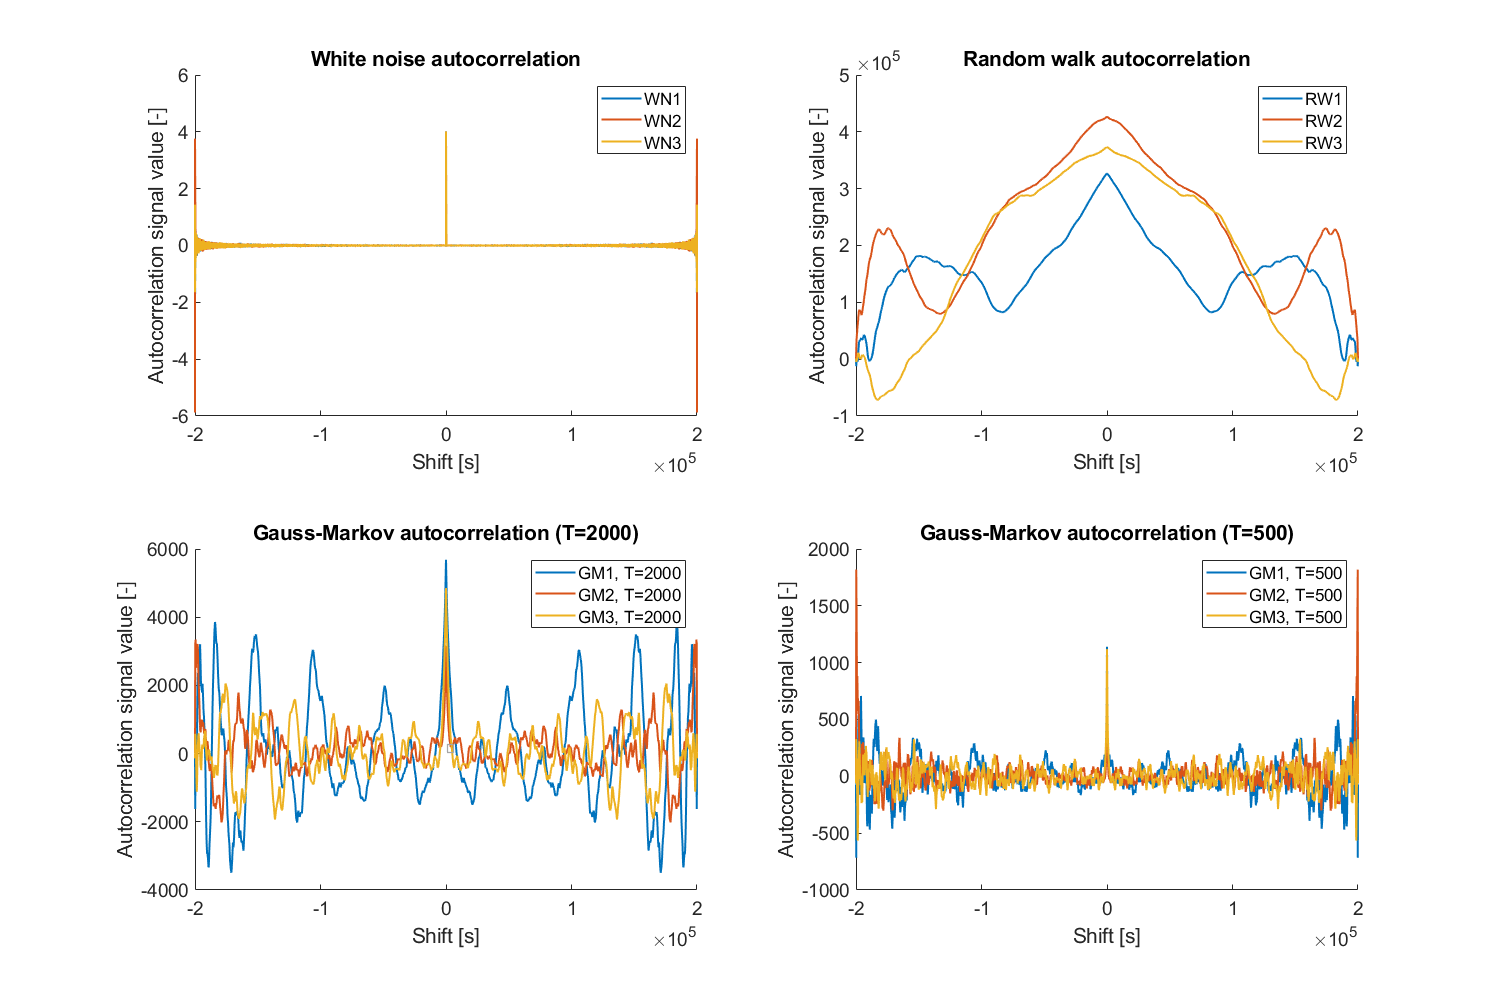

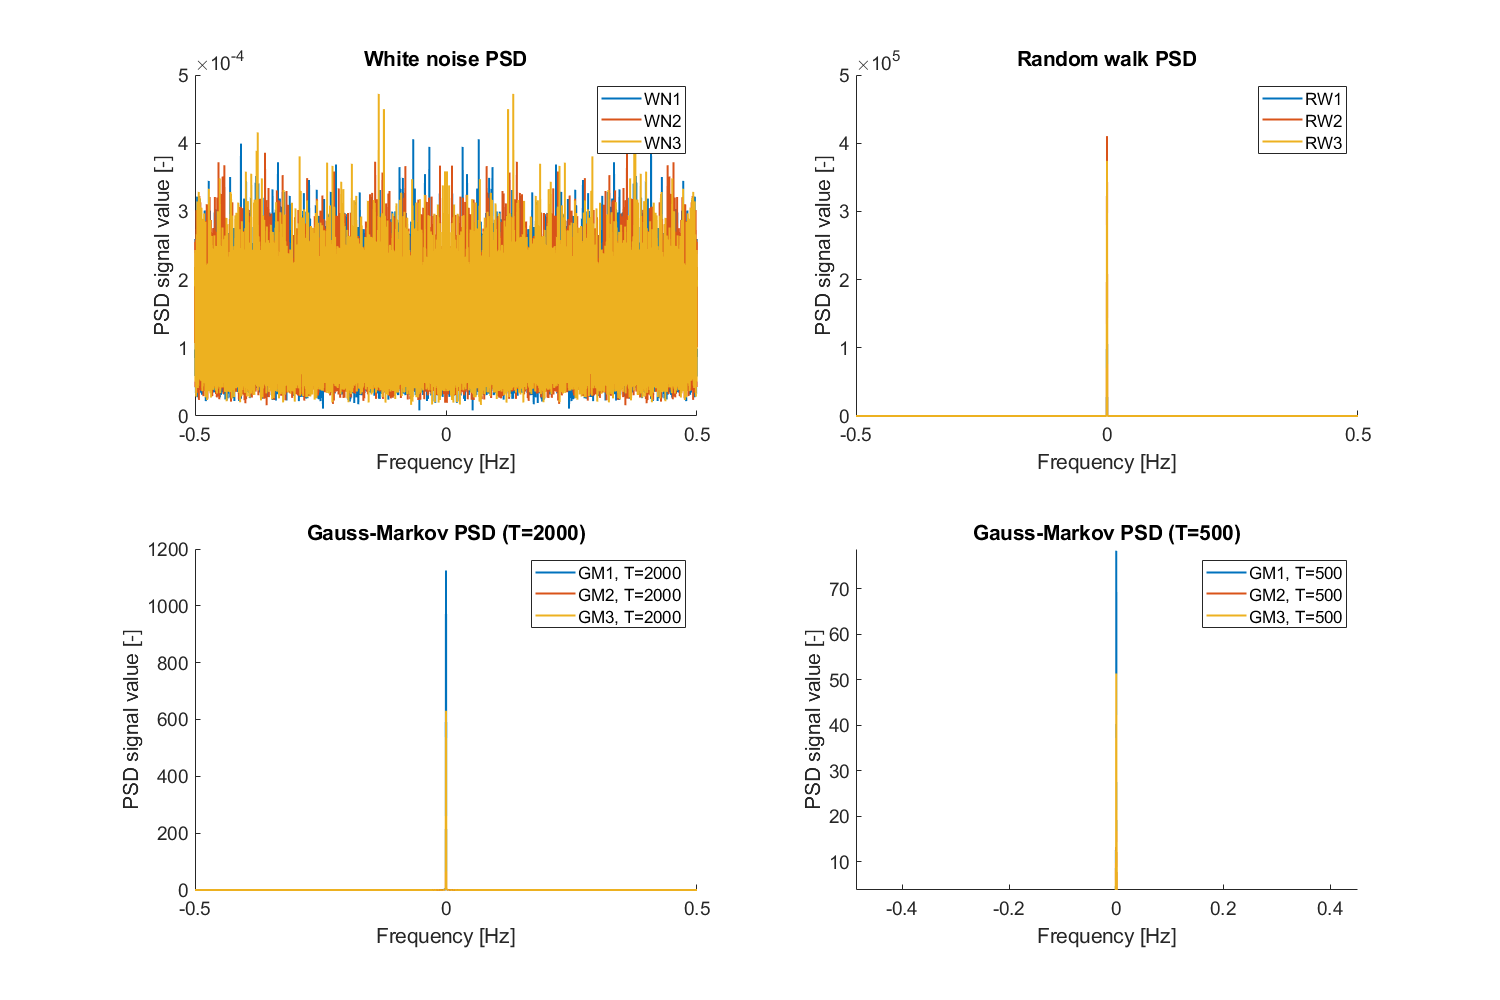

WN1 std. True: 	2	 Empirical 	 2.0056

WN2 std. True: 	2	 Empirical 	 2.0037

WN3 std. True: 	2	 Empirical 	 2.0032

GM1_500 std. True: 	31.6544	 Empirical 	 33.7713

GM2_500 std. True: 	31.6544	 Empirical 	 42.6395

GM3_500 std. True: 	31.6544	 Empirical 	 33.4463

GM1_2000 std. True: 	63.2614	 Empirical 	 75.3984

GM2_2000 std. True: 	63.2614	 Empirical 	 57.8433

GM3_2000 std. True: 	63.2614	 Empirical 	 69.6738

GM1_500 T. True: 	1472.1901	 Empirical 	 -103.2426

num_samples = 200000;

std_dev = 2;
fs = 1; % sampling frequency [Hz]

% Generate 3 random white noise sequences
% We set the seed to get the same noise when generating the other types of
% noises
rng(1)
noise_wn1 = generate_white_noise(num_samples, std_dev);

rng(2)
noise_wn2 = generate_white_noise(num_samples, std_dev);

rng(3)
noise_wn3 = generate_white_noise(num_samples, std_dev);

% Generate 3 random walks
rng(1)
noise_rw1 = generate_random_walk(num_samples, std_dev);

rng(2)
noise_rw2 = generate_random_walk(num_samples, std_dev);

rng(3)

noise_rw3 = generate_random_walk(num_samples, std_dev);

% Generate 3 realizations of 1st-order Gauss-Markov processes with
% correlation time T1 = 2000

T1 = 2000;

rng(1)
noise_gm1_2000 = generate_gauss_markov(num_samples, std_dev, 1/T1);

rng(2)
noise_gm2_2000 = generate_gauss_markov(num_samples, std_dev, 1/T1);

rng(3)
noise_gm3_2000 = generate_gauss_markov(num_samples, std_dev, 1/T1);

% Generate 3 realizations of 1st-order Gauss-Markov processes with
% correlation time T2 = 500

T2 = 500;

rng(1)
noise_gm1_500 = generate_gauss_markov(num_samples, std_dev, 1/T2);

rng(2)
noise_gm2_500 = generate_gauss_markov(num_samples, std_dev, 1/T2);

rng(3)
noise_gm3_500 = generate_gauss_markov(num_samples, std_dev, 1/T2);

% Save all noise realizations
save('noises.mat');

% Compute autocorrelation for each noise

% White noise
[corr_wn1, lag_wn1] = xcorr(noise_wn1, 'unbiased');
[corr_wn2, lag_wn2] = xcorr(noise_wn2, 'unbiased');
[corr_wn3, lag_wn3] = xcorr(noise_wn3, 'unbiased');

% Random walk
[corr_rw1, lag_rw1] = xcorr(noise_rw1, 'unbiased');
[corr_rw2, lag_rw2] = xcorr(noise_rw2, 'unbiased');
[corr_rw3, lag_rw3] = xcorr(noise_rw3, 'unbiased');

% Gauss-Markov
[corr_gm1_2000, lag_gm1_2000] = xcorr(noise_gm1_2000, 'unbiased');
[corr_gm2_2000, lag_gm2_2000] = xcorr(noise_gm2_2000, 'unbiased');
[corr_gm3_2000, lag_gm3_2000] = xcorr(noise_gm3_2000, 'unbiased');

[corr_gm1_500, lag_gm1_500] = xcorr(noise_gm1_500, 'unbiased');
[corr_gm2_500, lag_gm2_500] = xcorr(noise_gm2_500, 'unbiased');
[corr_gm3_500, lag_gm3_500] = xcorr(noise_gm3_500, 'unbiased');

% Compute power-spectral-density (PSD) for each noise

% White noise
[psd_wn1, f_wn1] = pwelch(noise_wn1, [], [], length(noise_wn1), fs, 'centered', 'power');
[psd_wn2, f_wn2] = pwelch(noise_wn2, [], [], length(noise_wn2), fs, 'centered', 'power');
[psd_wn3, f_wn3] = pwelch(noise_wn3, [], [], length(noise_wn3), fs, 'centered', 'power');

% Random walk
[psd_rw1, f_rw1] = pwelch(noise_rw1, [], [], length(noise_rw1), fs, 'centered', 'power');
[psd_rw2, f_rw2] = pwelch(noise_rw2, [], [], length(noise_rw2), fs, 'centered', 'power');
[psd_rw3, f_rw3] = pwelch(noise_rw3, [], [], length(noise_rw3), fs, 'centered', 'power');

% Gauss-Markov
[psd_gm1_2000, f_gm1_2000] = pwelch(noise_gm1_2000, [], [], length(noise_gm1_2000), fs, 'centered', 'power');
[psd_gm2_2000, f_gm2_2000] = pwelch(noise_gm2_2000, [], [], length(noise_gm2_2000), fs, 'centered', 'power');
[psd_gm3_2000, f_gm3_2000] = pwelch(noise_gm3_2000, [], [], length(noise_gm3_2000), fs, 'centered', 'power');

[psd_gm1_500, f_gm1_500] = pwelch(noise_gm1_500, [], [], length(noise_gm1_500), fs, 'centered', 'power');
[psd_gm2_500, f_gm2_500] = pwelch(noise_gm2_500, [], [], length(noise_gm2_500), fs, 'centered', 'power');
[psd_gm3_500, f_gm3_500] = pwelch(noise_gm3_500, [], [], length(noise_gm3_500), fs, 'centered', 'power');

% Compute Allan variance for each noise

% White noise
[av_wn1, tau_wn1] = allanvar(noise_wn1);
[av_wn2, tau_wn2] = allanvar(noise_wn2);
[av_wn3, tau_wn3] = allanvar(noise_wn3);

% Random walk
[av_rw1, tau_rw1] = allanvar(noise_rw1);
[av_rw2, tau_rw2] = allanvar(noise_rw2);
[av_rw3, tau_rw3] = allanvar(noise_rw3);

% Gauss-Markov
[av_gm1_2000, tau_gm1_2000] = allanvar(noise_gm1_2000);
[av_gm2_2000, tau_gm2_2000] = allanvar(noise_gm2_2000);
[av_gm3_2000, tau_gm3_2000] = allanvar(noise_gm3_2000);

[av_gm1_500, tau_gm1_500] = allanvar(noise_gm1_500);
[av_gm2_500, tau_gm2_500] = allanvar(noise_gm2_500);
[av_gm3_500, tau_gm3_500] = allanvar(noise_gm3_500);

% Increase font and line size
set(groot,'DefaultAxesFontSize',14)
set(groot,'DefaultLineLineWidth',1.5)

% Plot Figure 1 (noise)

% White noise
subplot(2, 2, 1);
hold on;
plot(noise_wn1);
plot(noise_wn2);
plot(noise_wn3);
title('White noise');
xlabel('Sample number [-]');
ylabel('Signal value [-]');
legend('WN1', 'WN2', 'WN3');

% Random walk
subplot(2, 2, 2);
hold on;
plot(noise_rw1);
plot(noise_rw2);
plot(noise_rw3);
title('Random walk');
xlabel('Sample number [-]');
ylabel('Signal value [-]');
legend('RW1', 'RW2', 'RW3');

% Gauss-Markov (T=2000)
subplot(2, 2, 3);
hold on;
plot(noise_gm1_2000);
plot(noise_gm2_2000);
plot(noise_gm3_2000);
title('Gauss-Markov (T=2000)');
xlabel('Sample number [-]');
ylabel('Signal value [-]');
legend('GM1, T=2000', 'GM2, T=2000', 'GM3, T=2000');

% Gauss-Markov (T=500)
subplot(2, 2, 4);
hold on;
plot(noise_gm1_500);
plot(noise_gm2_500);
plot(noise_gm3_500);
title('Gauss-Markov (T=500)');
xlabel('Sample number [-]');
ylabel('Signal value [-]');
legend('GM1, T=500', 'GM2, T=500', 'GM3, T=500');

% Plot Figure 2 (autocorrelation)

figure('Renderer', 'painters', 'Position', [10 10 1500 1000])

% White noise
subplot(2, 2, 1);
hold on;
plot(lag_wn1, corr_wn1);
plot(lag_wn2, corr_wn2);
plot(lag_wn3, corr_wn3);
title('White noise autocorrelation');
xlabel('Shift [s]');
ylabel('Autocorrelation signal value [-]');
legend('WN1', 'WN2', 'WN3');

% Random walk
subplot(2, 2, 2);
hold on;
plot(lag_rw1, corr_rw1);
plot(lag_rw2, corr_rw2);
plot(lag_rw3, corr_rw3);
title('Random walk autocorrelation');
xlabel('Shift [s]');
ylabel('Autocorrelation signal value [-]');
legend('RW1', 'RW2', 'RW3');

% Gauss-Markov (T=2000)
subplot(2, 2, 3);
hold on;
plot(lag_gm1_2000, corr_gm1_2000);
plot(lag_gm2_2000, corr_gm2_2000);
plot(lag_gm3_2000, corr_gm3_2000);
title('Gauss-Markov autocorrelation (T=2000)');
xlabel('Shift [s]');
ylabel('Autocorrelation signal value [-]');
legend('GM1, T=2000', 'GM2, T=2000', 'GM3, T=2000');

% Gauss-Markov (T=500)
subplot(2, 2, 4);
hold on;
plot(lag_gm1_500, corr_gm1_500);
plot(lag_gm2_500, corr_gm2_500);
plot(lag_gm3_500, corr_gm3_500);
title('Gauss-Markov autocorrelation (T=500)');
xlabel('Shift [s]');
ylabel('Autocorrelation signal value [-]');
legend('GM1, T=500', 'GM2, T=500', 'GM3, T=500');

% Plot figure 3 (PSD)

figure('Renderer', 'painters', 'Position', [10 10 1500 1000])

% White noise
subplot(2, 2, 1);
hold on;
plot(f_wn1, psd_wn1);
plot(f_wn2, psd_wn2);
plot(f_wn3, psd_wn3);
title('White noise PSD');
xlabel('Frequency [Hz]');
ylabel('PSD signal value [-]');
legend('WN1', 'WN2', 'WN3');

% Random walk
subplot(2, 2, 2);
hold on;
plot(f_rw1, psd_rw1);
plot(f_rw2, psd_rw2);
plot(f_rw3, psd_rw3);
title('Random walk PSD');
xlabel('Frequency [Hz]');
ylabel('PSD signal value [-]');
legend('RW1', 'RW2', 'RW3');

% Gauss-Markov (T=2000)
subplot(2, 2, 3);
hold on;
plot(f_gm1_2000, psd_gm1_2000);
plot(f_gm2_2000, psd_gm2_2000);
plot(f_gm3_2000, psd_gm3_2000);
title('Gauss-Markov PSD (T=2000)');
xlabel('Frequency [Hz]');
ylabel('PSD signal value [-]');
legend('GM1, T=2000', 'GM2, T=2000', 'GM3, T=2000');

% Gauss-Markov (T=500)
subplot(2, 2, 4);
hold on;
plot(f_gm1_500, psd_gm1_500);
plot(f_gm2_500, psd_gm2_500);
plot(f_gm3_500, psd_gm3_500);
title('Gauss-Markov PSD (T=500)');
xlabel('Frequency [Hz]');
ylabel('PSD signal value [-]');
legend('GM1, T=500', 'GM2, T=500', 'GM3, T=500');

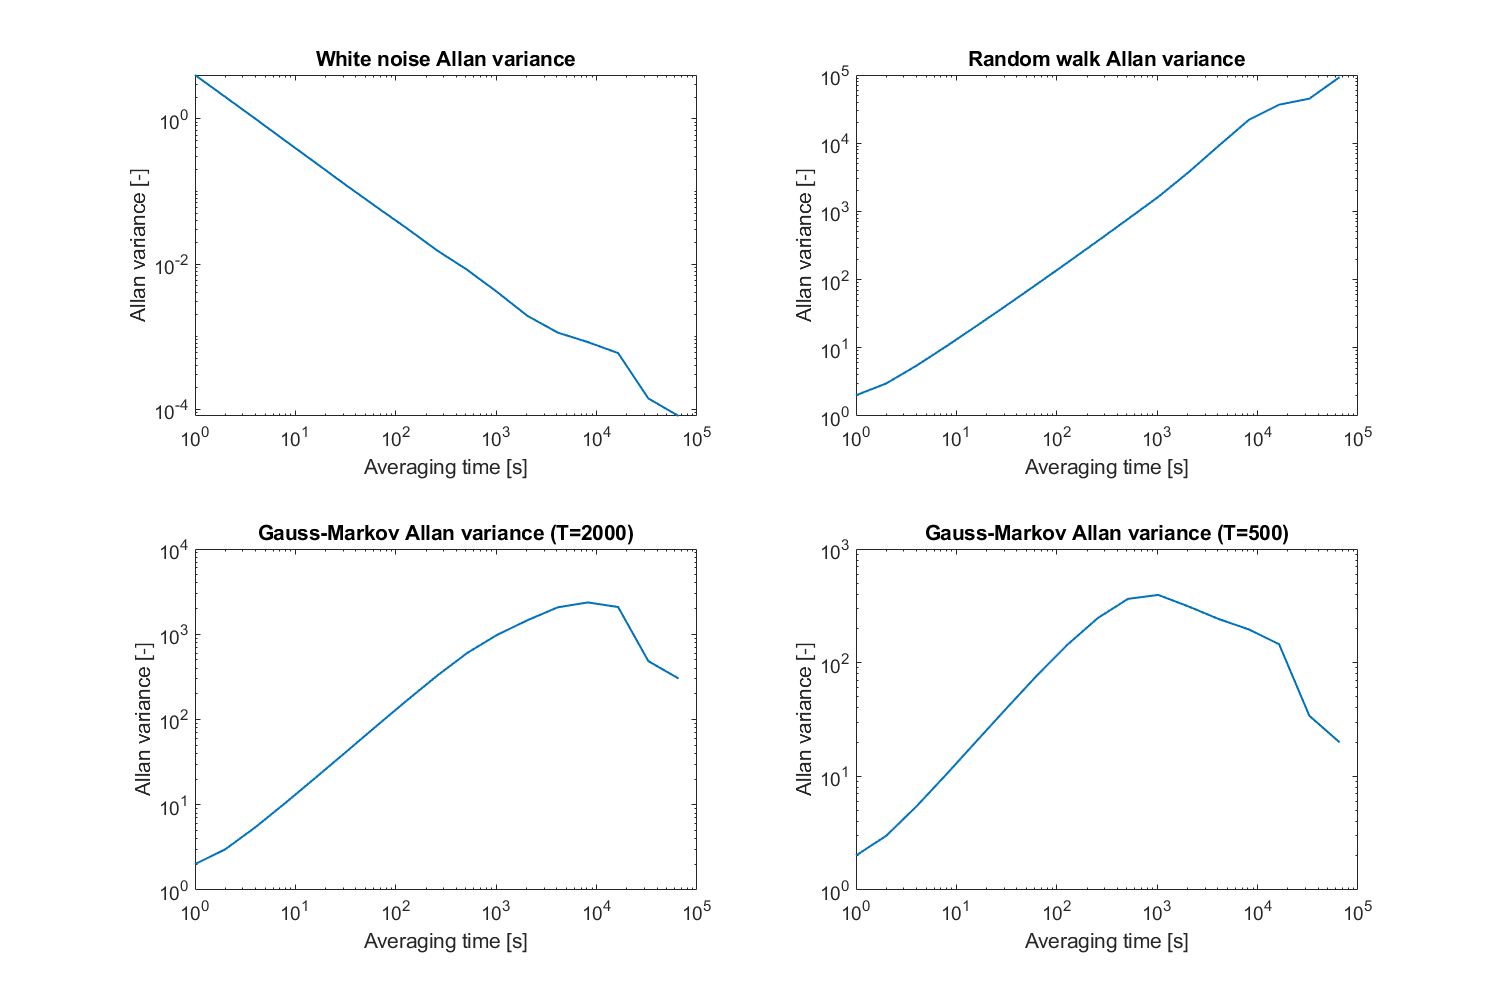

% Plot figure 4 (Allan variance)

figure('Renderer', 'painters', 'Position', [10 10 1500 1000])

subplot(2, 2, 1);
loglog(tau_wn1, av_wn1);
title('White noise Allan variance');
xlabel('Averaging time [s]');
ylabel('Allan variance [-]');

subplot(2, 2, 2);
loglog(tau_rw1, av_rw1);
title('Random walk Allan variance');
xlabel('Averaging time [s]');
ylabel('Allan variance [-]');

subplot(2, 2, 3);
loglog(tau_gm1_2000, av_gm1_2000);
title('Gauss-Markov Allan variance (T=2000)');
xlabel('Averaging time [s]');
ylabel('Allan variance [-]');

subplot(2, 2, 4);
loglog(tau_gm1_500, av_gm1_500);
title('Gauss-Markov Allan variance (T=500)');
xlabel('Averaging time [s]');
ylabel('Allan variance [-]');

% Check values of standard deviation and correlation length

% White noise =============================================
fprintf("WN1 std. True: \t" + std_dev + "\t Empirical \t " + std(noise_wn1));
fprintf("WN2 std. True: \t" + std_dev + "\t Empirical \t " + std(noise_wn2));
fprintf("WN3 std. True: \t" + std_dev + "\t Empirical \t " + std(noise_wn3));

% Random walk =============================================

% Gauss-Markov ============================================

% Using autocorrelation plot
fprintf("GM1_500 std. True: \t" + sqrt(std_dev^2/(1-(exp(-1/500*fs))^2)) + "\t Empirical \t " + sqrt(max(corr_gm1_500)));
fprintf("GM2_500 std. True: \t" + sqrt(std_dev^2/(1-(exp(-1/500*fs))^2)) + "\t Empirical \t " + sqrt(max(corr_gm2_500)));
fprintf("GM3_500 std. True: \t" + sqrt(std_dev^2/(1-(exp(-1/500*fs))^2)) + "\t Empirical \t " + sqrt(max(corr_gm3_500)));

fprintf("GM1_2000 std. True: \t" + sqrt(std_dev^2/(1-(exp(-1/2000*fs))^2)) + "\t Empirical \t " + sqrt(max(corr_gm1_2000)));
fprintf("GM2_2000 std. True: \t" + sqrt(std_dev^2/(1-(exp(-1/2000*fs))^2)) + "\t Empirical \t " + sqrt(max(corr_gm2_2000)));
fprintf("GM3_2000 std. True: \t" + sqrt(std_dev^2/(1-(exp(-1/2000*fs))^2)) + "\t Empirical \t " + sqrt(max(corr_gm3_2000)));


allan: allan v2.22

allan: regular data (200000 data points @ 1 Hz)
allan: calculating Allan deviation...
       allan: Minimum ADEV value: 0.00274292 at tau = 48969 seconds


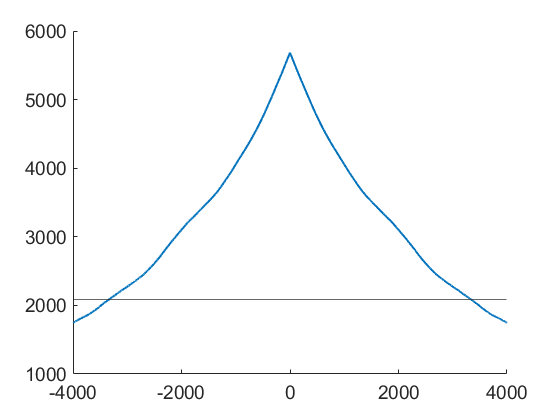

% For empirical estimation of correlation time

% T = 2000
figure
hold on
plot(lag_gm1_2000(num_samples-4000:num_samples+4000), corr_gm1_2000(num_samples-4000:num_samples+4000));
yline(max(corr_gm1_2000(num_samples-4000:num_samples+4000))*exp(-1));

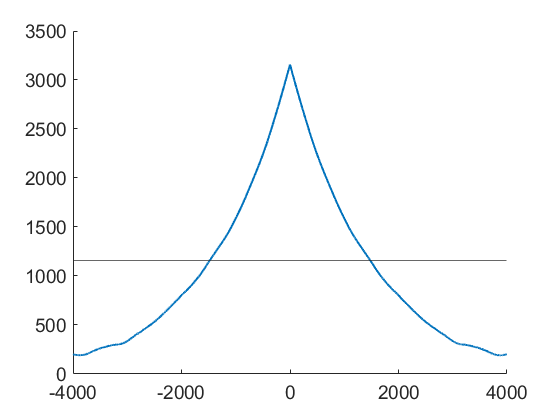

figure
hold on
plot(lag_gm2_2000(num_samples-4000:num_samples+4000), corr_gm2_2000(num_samples-4000:num_samples+4000));
yline(max(corr_gm2_2000(num_samples-4000:num_samples+4000))*exp(-1));

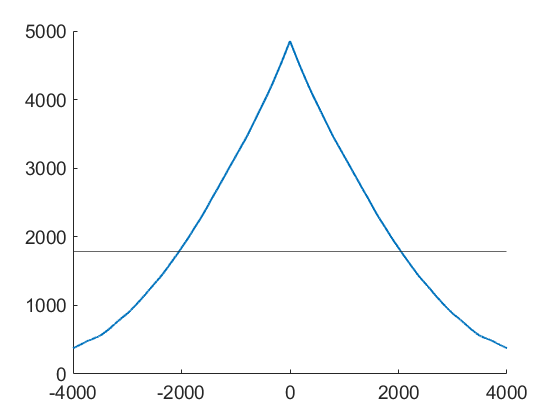

figure
hold on
plot(lag_gm3_2000(num_samples-4000:num_samples+4000), corr_gm3_2000(num_samples-4000:num_samples+4000));
yline(max(corr_gm3_2000(num_samples-4000:num_samples+4000))*exp(-1));

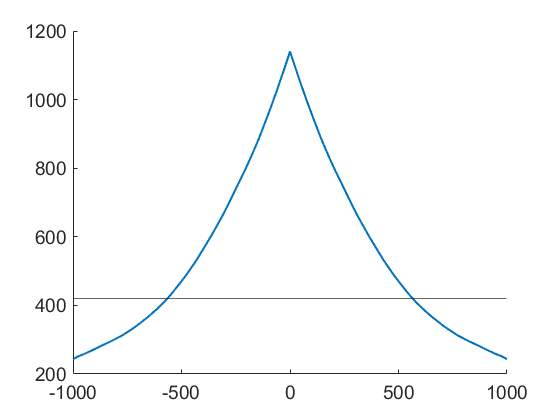


% T = 500
figure
hold on
plot(lag_gm1_500(num_samples-1000:num_samples+1000), corr_gm1_500(num_samples-1000:num_samples+1000));
yline(max(corr_gm1_500(num_samples-500:num_samples+500))*exp(-1));

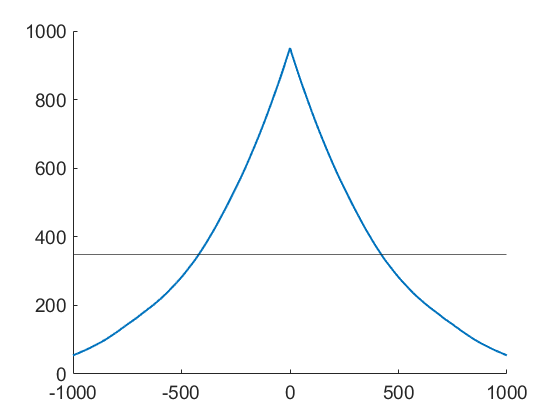

figure
hold on
plot(lag_gm2_500(num_samples-1000:num_samples+1000), corr_gm2_500(num_samples-1000:num_samples+1000));
yline(max(corr_gm2_500(num_samples-500:num_samples+500))*exp(-1));

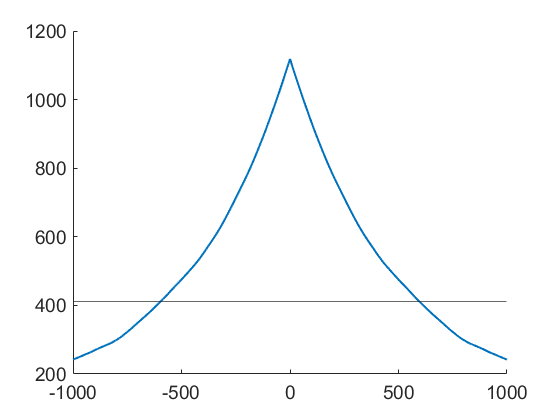

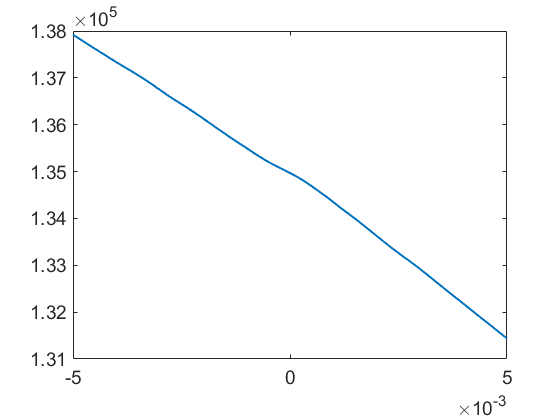

figure
hold on
plot(lag_gm3_500(num_samples-1000:num_samples+1000), corr_gm3_500(num_samples-1000:num_samples+1000));
yline(max(corr_gm3_500(num_samples-500:num_samples+500))*exp(-1));